# **Restrained beam under thermal expansion**

opsMAT = OpenSeesMatlab();
ops = opsMAT.opensees;

ops.wipe()
ops.model('basic', '-ndm', 2, '-ndf', 3);
% nodes
ops.node(1, 0.0, 0.0);
ops.node(2, 2.0, 0.0);
ops.node(3, 1.0, 0.0);

% boundary conditions
ops.fix(1, 1, 1, 1);
ops.fix(2, 1, 1, 1);
ops.fix(3, 0, 1, 1);

% material
matTag = 1;
ops.uniaxialMaterial('Steel01Thermal', matTag, 2e11, 2e11, 0.01);

% fiber section
secTag = 1;
ops.section('FiberThermal', secTag);
ops.fiber(-0.025, 0.0, 0.005, matTag);
ops.fiber( 0.025, 0.0, 0.005, matTag);

% coordinate transformation
transfTag = 1;
ops.geomTransf('Linear', transfTag);

% beam integration
np = 3;
biTag = 1;
ops.beamIntegration('Lobatto', biTag, secTag, np);

% elements
ops.element('dispBeamColumnThermal', 1, 1, 3, transfTag, biTag);
ops.element('dispBeamColumnThermal', 2, 3, 2, transfTag, biTag);

% time series
tsTag = 1;
ops.timeSeries('Linear', tsTag);

% load pattern
patternTag = 1;
maxtemp = 1000.0;
ops.pattern('Plain', patternTag, tsTag);
ops.eleLoad('-ele', 1, '-type', '-beamThermal', 1000.0, -0.05, 1000.0, 0.05);
% ops.eleLoad('-ele', 2, '-type', '-beamThermal', 0.0, -0.05, 0.0, 0.05);

% analysis
incrtemp = 0.01;
ops.system('BandGeneral');
ops.constraints('Plain');
ops.numberer('Plain');
ops.test('NormDispIncr', 1.0e-6, 100);
ops.algorithm('Newton');
ops.integrator('LoadControl', incrtemp);
ops.analysis('Static');

% run analysis
nstep = 100;
temp = zeros(nstep + 1, 1);
disp = zeros(nstep + 1, 1);

temp(1) = 0.0;
disp(1) = 0.0;

for i = 1:nstep
    ok = ops.analyze(1);
    if ok < 0
        temp = temp(1:i);
        disp = disp(1:i);
        break;
    end

    temp(i + 1) = ops.getLoadFactor(patternTag) * maxtemp;
    disp(i + 1) = ops.nodeDisp(3, 1);
end

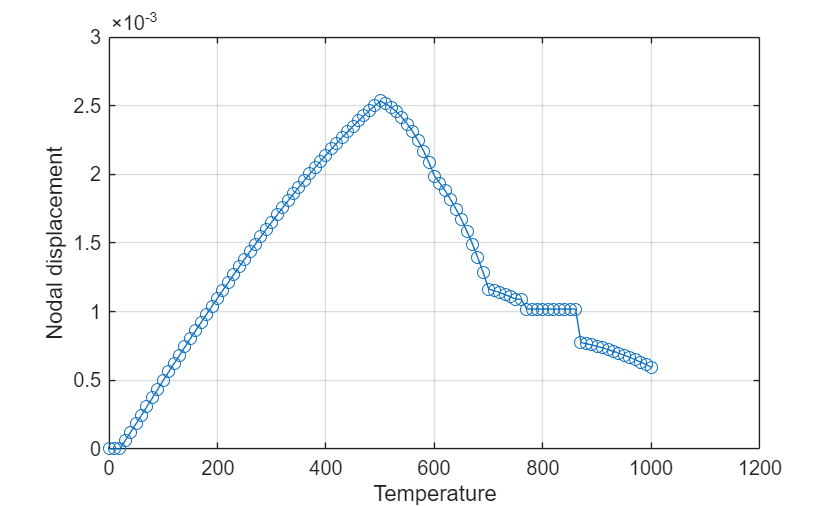

% plot
figure;
plot(temp, disp, '-o');
xlabel('Temperature');
ylabel('Nodal displacement');
grid on;